clc; clear all;

% Mass of the crane M
M = 1000; 
% Mass of the weight m1
m1 = 100;
% Mass of the weight m2
m2 = 100;
% Length of cable 1
l1 = 20;
% Length of cable 2
l2 = 10;
% gravity g
g = 9.8;

A = [0  1      0            0       0           0;
     0  0   (-m1*g)/M       0   (-m2*g)/M       0;
     0  0      0            1       0           0;
     0  0   (-(m1+M)*g)/(M*l1)  0   (-m2*g)/(M*l1)  0;
     0  0      0            0       0           1;
     0  0   (-m1*g)/(M*l2)  0   (-(m2+M)*g)/(M*l2)  0];
 
B = [0;
    (1/M);
     0;
    (1/(M*l1));
     0;
    (1/(M*l2))];

C = [1 0 0 0 0 0]; 
D=0;


n_states = 6; 
sys = ss(A,B,C,D);
Qn = ones(n_states);
Rn = 0.7;
R = [1];
QXU = blkdiag(0.1*eye(n_states),R);
QWV = blkdiag(Qn,Rn)

QWV =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0
         0         0         0         0         0         0    0.7000


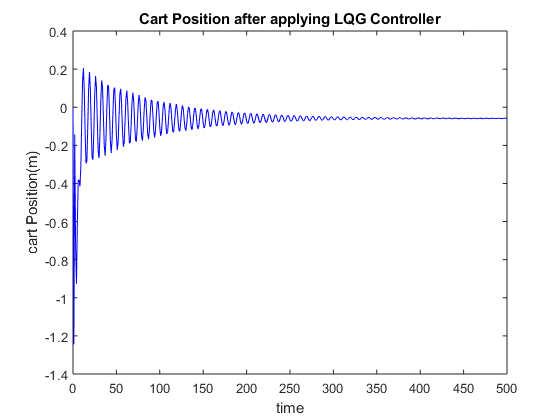


KLQG = lqg(sys,QXU,QWV);

A_LQG = KLQG.A;
B_LQG = KLQG.B;
C_LQG = KLQG.C;
D_LQG = KLQG.D;

t = 0:1:500;
r = [0.2*ones(size(t))];
[y,t,x]=lsim(KLQG,r,t);
y1 = y(:,1);
plot(t,y1,'b');
title('Cart Position after applying LQG Controller')
xlabel('time')
ylabel('cart Position(m)')